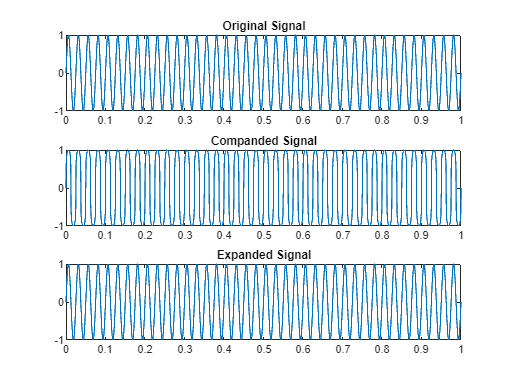


% Example usage
fs = 44100; % Sampling frequency
t = 0:1/fs:1; % Time vector
f = 40; % Frequency of a 440 Hz sine wave
x = sin(2 * pi * f * t); % Original sine wave signal

mu = 255; % Parameter for μ-law companding

% Apply μ-law companding
compressed_signal = mu_law_compand(x, mu);

% Apply μ-law expansion
expanded_signal = mu_law_expand(compressed_signal, mu);

% Plot the original and compressed signals
figure;
subplot(3, 1, 1);
plot(t, x);
title('Original Signal');

subplot(3, 1, 2);
plot(t, compressed_signal);
title('Companded Signal');

subplot(3, 1, 3);
plot(t, expanded_signal);
title('Expanded Signal');

function compressed_signal = mu_law_compand(input_signal, mu)
    % Ensure the input signal is in the range [-1, 1]
    input_signal = max(-1, min(1, input_signal));
    
    % Apply μ-law companding
    compressed_signal = sign(input_signal) .* log(1 + mu * abs(input_signal)) / log(1 + mu);
end

function expanded_signal = mu_law_expand(companded_signal, mu)
    % Apply μ-law expansion
    expanded_signal = sign(companded_signal) .* ((1 / mu) * ((1 + mu).^abs(companded_signal) - 1));
end
